# **Esercitazione n*7 - Deconvoluzione**

## **Descrizione del problema **

E’ stato fatto un test (chiamato up & down) di risposta glicemica in un soggetto. E’ stata misurata nel tempo la concentrazione plasmatica di C-peptide. I dati sono stati raccolti nel file datiEs7.m. La prima colonna riporta il tempo (in minuti), la seconda la concentrazione di C-pepdite (in pmol/ml), yb e' la concentrazione basale di C-peptide misurata prima dell’effettuazione dell’esperimento. Sapendo che il soggetto ha le seguenti caratteristiche:

-  stato di salute: normale

-  altezza: 164 cm

- peso: 59,6 kg

- eta': 32

- sesso: F

determinare i parametri della cinetica del C-peptide di questo soggetto usando il modello trovato nell’esercitazione precedente. Stimare la secrezione insulinica usando il metodo della raw deconvolution e della regolarizzazione (variare il gamma e trovare il gamma ottimo).

## Considerazioni sulla deconvoluzione

Molti segnali di interesse per la caratterizzazione quantitativa di sistemi fisiologici non sono direttamente misurabili in vivo. Esempi sono il rate di secrezione di una ghiandola e il rate di comparsa di un farmaco nel plasma dopo una somministrazione orale. In questi casi e' possibile misurare esclusivamente gli effetti finali prodotti e sorge quindi la necessita' di individuare le cause sconosciute che li hanno generati. Il problema della stima dell'ingresso, nel caso di un sistema LTI, puo' essere cosi' formulato: 


$$c\left(t\right)=\int_0^t g\left(t-\tau \right)u\left(\tau \right)d\tau$$


dove $u\left(t\right)$e' l'ingresso sconosciuto da ricostruire e $c\left(t\right)$e' l'uscita misurabile del sistema. La funzione $g\left(t\right)$e' la risposta impulsiva che descrive la relazione ingresso-uscita quando il sitema viene stimolato da un ingresso impulsivo unitario. Il problema della deconvoluzione notoriamente conosciuto per essere "*mal posto*", necessita di due considerazioni importanti: 

- un piccolo errore nell'uscita misurata puo' produrre un errore piu' grande nella stima dell'ingresso;

- la risposta impulsiva $g\left(t\right)$e' un modello, spesso una somma di esponanziali, identificato a partire da specifici esperimenti ingresso-uscita o ottenuto da studi di popolazione. 

clearvars;
close all;
clc;

## Lettura dei dati

I dati di cincentrazione e tempi sono contenuti nel file `datiEs7.m`. I parametri stimati per il soggetto in esame della cinetica del C-peptide sono contenuti nel file `stimaEs7.m`.

datiEs7;  % Dati di concentrazione
stimaEs7; % Parametri soggetto 

t = DATA(:,1); % Tempi (min)
c = DATA(:,2); % Concentrazioni (pmol/ml)

## Raw Deconvolution

Il metodo della Raw Deconvolution e' il metodo di deconvoluzione piu' semplice. Supponendo di aver a disposizione un set discreto $z_k =y_k +v_k$con $v_k$, errore di misura, con la RD si trascura quest'ultimo. Il problema da risolvere e' $z=\mathrm{Gu}$ la cui soluzione e' $u=G^{-1} z$. Affiche' il problema sia risolvibile la matrice $G$ deve avere le seguenti caratteristiche:

- matrice quadrata (m=n, percio' la griglia virtuale deve avere le stesse dimensioni di quella di campionamento);

- matrice triangolare inferiore e di Toepliz.

% Calcolo dei parametri della relazione ingresso-uscita (da quelli stimati)
alfa = log(2)/temp_emi_short;
beta = log(2)/temp_emi_long;
A = fraction/vol;
B = (1-fraction)/vol;

Il segnale $u\left(t\right)$che verra' ricostruito e' assunto costante a tratti in ogni intervallo di tempo della griglia vistuale $\left\lbrace t_1 ,t_2 ,\;\ldotp \ldotp \ldotp \;,t_m \right\rbrace$, cioe' $u\left(t\right)=u_i$ per $t_{i-1} <t\le t_i$ dove $t=0$. Sfruttando tale ipotesi si ha 


$$y_k =\sum_{i=1}^k u_i \int_{t_i -1}^{t_i } g\left(t_k -\tau \right)d\tau$$


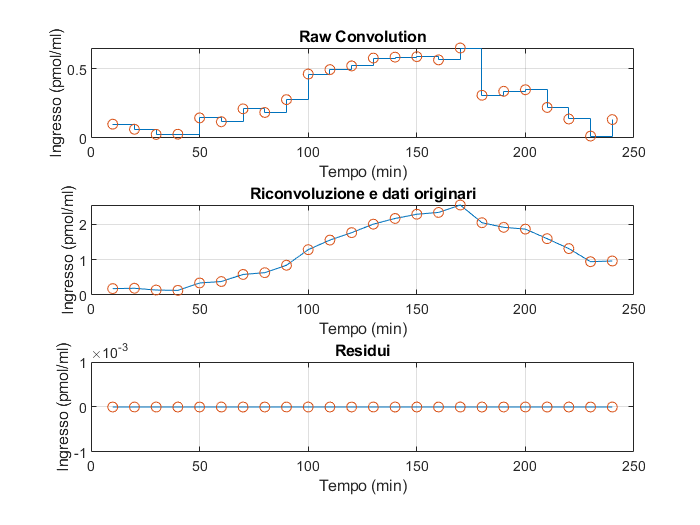

n = length(c);
t_comp = [0,t']';

g = zeros(1,length(t));

% Calcolo l'integrale in modo da ricavare g_tilde
for i = 1:length(t)
    int = [t_comp(i),t_comp(i+1)];
    g(i) = trapz(int,A*exp(-int*alfa)+B*exp(-int*beta));
end

G = zeros(n);

% Calcolo la matrice G 
for i = 1:n
    for j = i:n
        G(j,i) = g(j-i+1);
    end
end

% Sottrazione del valore basale alle misure di concentrazione
z = c - yb;
% Ricostruzione dell'ingresso
u = G\z;

% Riconvoluzione
z_riconv = G*u;
% Calcolo dei residui
res = z - z_riconv;

subplot(3,1,1), stairs(t,u), hold on, stairs(t,u,'o'),  
xlabel("Tempo (min)"), ylabel("Ingresso (pmol/ml)"), title("Raw Convolution"), grid on; 
subplot(3,1,2), plot(t,z_riconv,t,z,'o'), 
xlabel("Tempo (min)"), ylabel("Ingresso (pmol/ml)"), title("Riconvoluzione e dati originari"), grid on; 
subplot(3,1,3), plot(t,res,t,zeros(length(t),1),'o'), 
xlabel("Tempo (min)"), ylabel("Ingresso (pmol/ml)"), title("Residui"), 
ylim([-0.001,0.001]), grid on;   